clear 
clc


addpath '.\INM'
addpath '.\SD'
addpath '.\FR'
addpath '.\functions'

load('forcing_terms.mat')
load('test_functions2.mat')
load('myFunctions.mat')

%Armijo
c1 = 1e-4;
rho = 0.5;
btmax = 50;
alpha0 = 1;

%Step for finite differences
h = 1e-8;

%Problem definition
n = 1000;
x0 = x14(n);
f = f14;
gradf = gf14;
Hessf = 0;

kmax = 50000;
tolgrad = 1.0E-6;
toldiffgrad = 1e-12;

% max number of iterations for the pcg
pcg_maxit = 200;

run_steepest = true;
run_fr = true;
run_newton = true;

%P5 -> Converges (with tolgrad or kmax easier)
%P13 -> Converges
%P14 -> Converge (con pcgmax=200,ci mette un botto)
%P23 

##     Run Steepest Descent

if run_steepest
    disp('***Steepest Descent: start***')
    tic
    [xk_sd, fk_sd, gradfk_norm_sd, k_sd, xseq_sd, btseq_sd, fseq_sd, gfseq_sd] = ... 
        steepest_desc_bt(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax)
    
    disp('***Steepest Descent: finished')
    toc
    disp('***SD: results')
    disp('*******')
    disp(['xk: ', mat2str(xk_sd)])
    disp(['f(xk): ', mat2str(fk_sd)])
    disp(['gradf(xk): ', mat2str(gradfk_norm_sd)])
    disp(['N of iterations: ', num2str(k_sd), '/', num2str(kmax), ';'])
    
    disp('****')
else
    disp("SD Method not runned")
end

***Steepest Descent: start***


Iteration 1 gf_norm: 0.001495
Iteration 2 gf_norm: 0.001494
Iteration 3 gf_norm: 0.001493
Iteration 4 gf_norm: 0.001492
Iteration 5 gf_norm: 0.001492
Iteration 6 gf_norm: 0.001491
Iteration 7 gf_norm: 0.001491
Iteration 8 gf_norm: 0.001491
Iteration 9 gf_norm: 0.001491
Iteration 10 gf_norm: 0.001491
Iteration 11 gf_norm: 0.001491
Iteration 12 gf_norm: 0.001491
Iteration 13 gf_norm: 0.001491
Iteration 14 gf_norm: 0.001491
Iteration 15 gf_norm: 0.001491
Iteration 16 gf_norm: 0.001491
Iteration 17 gf_norm: 0.001491
Iteration 18 gf_norm: 0.001491
Iteration 19 gf_norm: 0.001491
Iteration 20 gf_norm: 0.001491
Iteration 21 gf_norm: 0.001491
Iteration 22 gf_norm: 0.001491
Iteration 23 gf_norm: 0.001491
Iteration 24 gf_norm: 0.001491
Iteration 25 gf_norm: 0.001491
Iteration 26 gf_norm: 0.001491
Iteration 27 gf_norm: 0.001491
Iteration 28 gf_norm: 0.001491
Iteration 29 gf_norm: 0.001491
Iteration 30 gf_norm: 0.001491
Iteration 31 gf_norm: 0.001491
Iteration 32 gf_norm: 0.001491
Iteration 33 gf_n

xk_sd =     0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0069
    0.0079
    0.0089
    0.0099


fk_sd = 2.1639e-08

gradfk_norm_sd = 0.0015

k_sd = 50000

xseq_sd =     0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010
    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.002

btseq_sd =      4     5     5     6     4     6     6    37    45    46    46    47    46    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48    48


fseq_sd = 1.0e-07 *

    0.2170    0.2168    0.2167    0.2166    0.2165    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164


gfseq_sd =     0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015


***Steepest Descent: finished


Elapsed time is 1148.956227 seconds.


***SD: results


*******


xk: [0.000996363678887881;0.00199202474342742;0.00298611809560985;0.00397822658089646;0.00496826460704883;0.00595627221958838;0.0069422854480302;0.00792630734849091;0.00890833323849533;0.00988836274249233;0.0108663962380546;0.0118424337073798;0.0128164751377472;0.0137885205315445;0.0147585698885491;0.0157266232087186;0.0166926804920065;0.0176567417383664;0.0186188069477521;0.0195788761201177;0.0205369492554178;0.0214930263536069;0.0224471074146401;0.0233991924384725;0.0243492814250598;0.0252973743743577;0.0262434712863223;0.02718757216091;0.0281296769980775;0.0290697857977817;0.03000789855998;0.0309440152846299;0.0318781359716892;0.0328102606211162;0.0337403892328693;0.0346685218069073;0.0355946583431894;0.0365187988416749;0.0374409433023236;0.0383610917250955;0.0392792441099511;0.040195400456851;0.0411095607657563;0.0420217250366284;0.0429318932694289;0.0438400654641199;0.0447462416206637;0.0456504217390232;0.0465526058191612;0.0474527938610412;0.0483509858646271;0.0492471818298828;0.

f(xk): 2.16389825346679e-08


gradf(xk): 0.00149108142078382


N of iterations: 50000/50000;


****


**Run FR**

if run_fr
    disp('***FR: start***')
    tic
    [xk, fk, gradfk_norm, k_fr, xseq_fr, btseq_fr, fseq_fr, gfseq_fr] = fletcher_reeves(x0, f, gradf, alpha0, kmax, tolgrad, c1, rho, btmax)
    
    disp('***FR: finished')
    toc
    disp('***FR: results')
    disp('*******')
    disp(['xk: ', mat2str(xk)])
    disp(['f(xk): ', mat2str(fk)])
    disp(['gradf(xk): ', mat2str(gradfk_norm)])
    disp(['N of iterations: ', num2str(k_fr), '/', num2str(kmax), ';'])
    
    disp('****')
else
    disp("FR Method not runned")
end

***FR: start***


Iteration 1 gf_norm: 0.001495
Iteration 2 gf_norm: 0.001493
Iteration 3 gf_norm: 0.001492
Iteration 4 gf_norm: 0.001491
Iteration 5 gf_norm: 0.001491
Iteration 6 gf_norm: 0.001491
Iteration 7 gf_norm: 0.001491
Iteration 8 gf_norm: 0.001490
Iteration 9 gf_norm: 0.001490
Iteration 10 gf_norm: 0.001490
Iteration 11 gf_norm: 0.001490
Iteration 12 gf_norm: 0.001490
Iteration 13 gf_norm: 0.001490
Iteration 14 gf_norm: 0.001490
Iteration 15 gf_norm: 0.001490
Iteration 16 gf_norm: 0.001490
Iteration 17 gf_norm: 0.001490
Iteration 18 gf_norm: 0.001490
Iteration 19 gf_norm: 0.001490
Iteration 20 gf_norm: 0.001490
Iteration 21 gf_norm: 0.001490
Iteration 22 gf_norm: 0.001490
Iteration 23 gf_norm: 0.001490
Iteration 24 gf_norm: 0.001490
Iteration 25 gf_norm: 0.001490
Iteration 26 gf_norm: 0.001490
Iteration 27 gf_norm: 0.001490
Iteration 28 gf_norm: 0.001490
Iteration 29 gf_norm: 0.001490
Iteration 30 gf_norm: 0.001490
Iteration 31 gf_norm: 0.001490
Iteration 32 gf_norm: 0.001490
Iteration 33 gf_n

xk =     0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0069
    0.0079
    0.0089
    0.0099


fk = 2.1614e-08

gradfk_norm = 0.0015

k_fr = 50000

xseq_fr =     0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010
    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.002

btseq_fr =      4     5     6     6     8     7    40     9    10    10    13    11    37    13    13    15    14    14    16    15    16    16    16    16    17    17    17    17    18    18    18    18    18    19    19    19    19    19    19    20    20    19    22    20    20    20    21    21    20    23


fseq_fr = 1.0e-07 *

    0.2170    0.2167    0.2166    0.2164    0.2164    0.2163    0.2163    0.2162    0.2162    0.2162    0.2162    0.2162    0.2162    0.2162    0.2162    0.2162    0.2162    0.2162    0.2162    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161    0.2161


gfseq_fr =     0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015


***FR: finished


Elapsed time is 1052.592355 seconds.


***FR: results


*******


xk: [0.000995636224688956;0.00199092761189814;0.00298511673515387;0.00397734801707693;0.00496736390468262;0.00595535319037488;0.00694136524095777;0.00792538293061675;0.00890740377926535;0.0098874285473665;0.0108654572806327;0.0118414899617435;0.0128155265904292;0.0137875671668256;0.0147576116908587;0.015725660162456;0.0166917125815486;0.0176557689480641;0.018617829261936;0.0195778935230934;0.0205359617314677;0.0214920338869918;0.0224461099895971;0.023398190039216;0.0243482740357816;0.0252963619792283;0.0262424538694887;0.0271865497064981;0.0281286494901904;0.0290687532205017;0.0300068608973674;0.0309429725207229;0.0318770880905054;0.0328092076066539;0.0337393310691015;0.034667458477789;0.0355935898326549;0.0365177251336371;0.0374398643806755;0.038360007573703;0.039278154712673;0.0401943057975225;0.041108460828189;0.0420206198046155;0.0429307827267427;0.043838949594517;0.0447451204078803;0.0456492951667745;0.0465514738711472;0.047451656520942;0.0483498431161038;0.0492460336565791;0.0501

f(xk): 2.16140396305663e-08


gradf(xk): 0.00148995479220127


N of iterations: 50000/50000;


****


### **Run the Newton**

if run_newton
    kmax = 100
    % fterms = @(gradf, x, k) 0.5;
    % fterms = @(gradfk, k) min(0.5, sqrt(norm(gradfk)));
    fterms = @(gradfk, k) min(0.5, norm(gradfk));
    
    % options for finite differences
    FDgrad = 'c';
    FDHess = 'fw';
    
    disp('***IN. NEWTON F.D. options***')
    disp(['FDgrad: ', FDgrad])
    disp(['FDHess: ', FDHess])
    
    disp('***Newton: start***')
    tic
    [xk, fk, gradfk_norm, k_inm, xseq, btseq, fseq, gfseq] = ...
    innewton_general(x0, f, gradf, Hessf, kmax, ...
    tolgrad, toldiffgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit)
    
    disp('***IN. newton: finished')
    toc
    disp('***newton: results')
    disp('*******')
    disp(['xk: ', mat2str(xk)])
    disp(['f(xk): ', mat2str(fk)])
    disp(['gradf(xk): ', mat2str(gradfk_norm)])
    disp(['N of iterations: ', num2str(k_inm), '/', num2str(kmax), ';'])
    
    disp('****')
else
    disp("Newton Method not runned")
end

kmax = 100

***IN. NEWTON F.D. options***


FDgrad: c


FDHess: fw


***Newton: start***


 
Hessian non-PD
pcg stopped at iteration 200 without converging to the desired tolerance 1.3e-05
because the maximum number of iterations was reached.
The iterate returned (number 200) has relative residual 0.26.
gradfk_norm: 0.000013 
Hessian non-PD
pcg stopped at iteration 200 without converging to the desired tolerance 1.3e-05
because the maximum number of iterations was reached.
The iterate returned (number 200) has relative residual 0.26.
gradfk_norm: 0.000013 
Hessian non-PD
pcg stopped at iteration 200 without converging to the desired tolerance 1.3e-05
because the maximum number of iterations was reached.
The iterate returned (number 200) has relative residual 0.26.
gradfk_norm: 0.000013     0



xk =     0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0069
    0.0079
    0.0089
    0.0099


fk = 2.1727e-08

gradfk_norm = 1.2974e-05

k_inm = 3

xseq =     0.0010    0.0010    0.0010
    0.0020    0.0020    0.0020
    0.0030    0.0030    0.0030
    0.0040    0.0040    0.0040
    0.0050    0.0050    0.0050
    0.0060    0.0060    0.0060
    0.0069    0.0069    0.0069
    0.0079    0.0079    0.0079
    0.0089    0.0089    0.0089
    0.0099    0.0099    0.0099


btseq =     50    50    50


fseq = 1.0e-07 *

    0.2173    0.2173    0.2173


gfseq = 1.0e-04 *

    0.1297    0.1297    0.1297


***IN. newton: finished


Elapsed time is 3216.590069 seconds.


***newton: results


*******


xk: [0.000998002996004994;0.00199400998601798;0.00298802097003895;0.00398003594806792;0.00497005492010487;0.00595807788614981;0.00694410484620275;0.00792813580026367;0.00891017074833259;0.00989020969040949;0.0108682526264944;0.0118442995565873;0.0128183504806881;0.013790405398797;0.0147604643109139;0.0157285272170387;0.0166945941171715;0.0176586650113124;0.0186207398994612;0.019580818781618;0.0205389016577828;0.0214949885279556;0.0224490793921363;0.0234011742503251;0.0243512731025219;0.0252993759487266;0.0262454827889393;0.0271895936231601;0.0281317084513888;0.0290718272736255;0.0300099500898702;0.0309460769001229;0.0318802077043835;0.0328123425026522;0.0337424812949288;0.0346706240812135;0.0355967708615061;0.0365209216358067;0.0374430764041154;0.038363235166432;0.0392813979227566;0.0401975646730892;0.0411117354174297;0.0420239101557783;0.0429340888881348;0.0438422716144994;0.0447484583348719;0.0456526490492524;0.046554843757641;0.0474550424600375;0.048353245156442;0.0492494518468544;0

f(xk): 2.17268193592995e-08


gradf(xk): 1.29741233475527e-05


N of iterations: 3/100;


****


disp('===========================================================================================================================================================================')

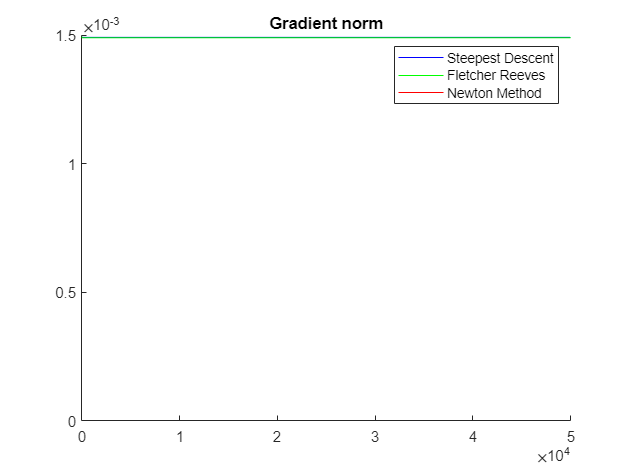

figure(1);
hold on;
title("Gradient norm")
plot(linspace(0,k_sd,k_sd), gfseq_sd, "b")
plot(linspace(0,k_fr,k_fr), gfseq_fr, "g")
plot(linspace(0,k_inm,k_inm), gfseq, "r")
legend(["Steepest Descent", "Fletcher Reeves", "Newton Method"])
hold off;

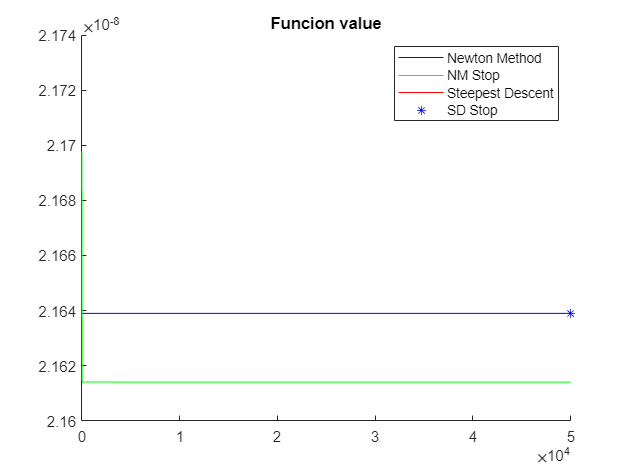

figure(2);
hold on;
title("Funcion value")
plot(linspace(0,k_sd,k_sd), fseq_sd, "b")
plot(linspace(0,k_fr,k_fr), fseq_fr, "g")
plot(linspace(0,k_inm,k_inm), fseq, "r")

plot(k_sd, fseq_sd(k_sd), "*b")
legend("Newton Method","NM Stop", "Steepest Descent", "SD Stop")
hold off;

% disp_int = [-1 1];
% 
% f1_meshgrid = @(X,Y)reshape(f([X(:),Y(:)]'),size(X));
% fcontour(f1_meshgrid, disp_int, 'Fill','on');
% hold on
% h = plot(xseq(1,:), xseq(2,:), '-*r', 'linewidth', 1, 'markersize', 5);
% hold off

% % creation of meshgrid for the contour-plot
% [X1, Y1] = meshgrid(linspace(-2, 2, 500), linspace(-2, 2, 500));
% 
% % computation of the values of f for each point of the mesh
% % Z1 = (1-X1).^2 + 100 * (Y1-X1.^2).^2;
% 
% % Plots
% 
% % simple plot
% fig1_n = figure();
% 
% % contour plot with curve levels for each point in xseq
% % [C1, ~] = contour(X1, Y1, Z1, [1, 10, 50, 100:1000:9000]);
% 
% hold on
% % plot of the points in xseq
% plot([x0(1) xseq(1, :)], [x0(2) xseq(2, :)], '-*', color="r")
% 
% hold off
% title('Inexact Newton')
